# Time evolution for the linear Schrodinger equation on a lollipop graph

Evolves the linear Schrodinger equation through time.

## Set up the graph structure and coordinates of the problem

By default, the discretization type is uniform but you may choose it to be Chebyshev for the time evolution. You can also set other properties such as the number of discretization points per edge.

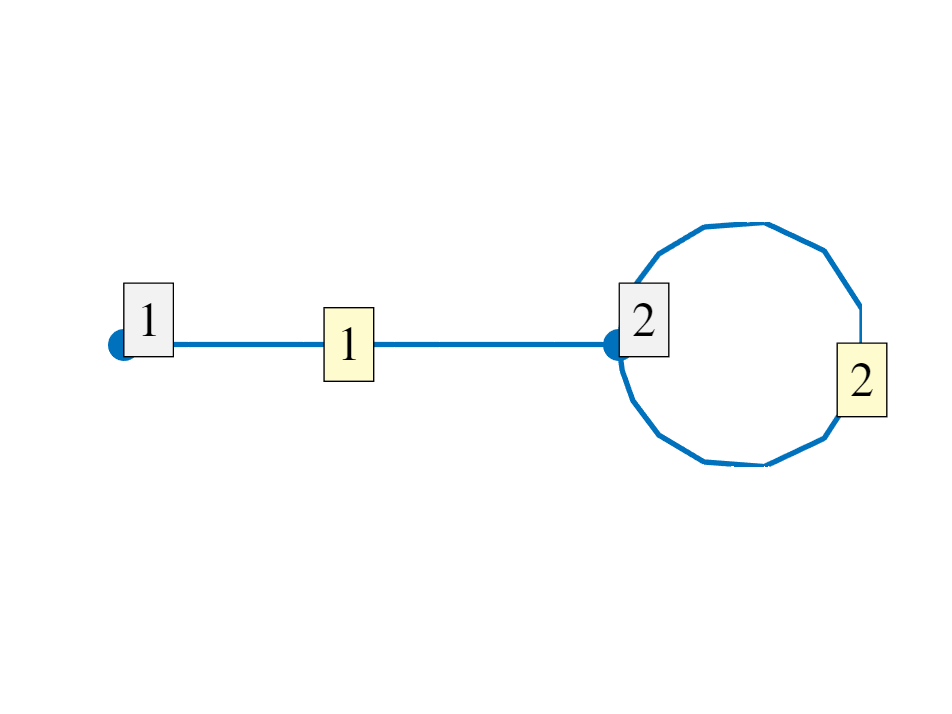

Phi = quantumGraphFromTemplate('multibell','discretization','Chebyshev','nX',32,'nbells',1);
Phi.plot('layout')

## Define the function

We define the linear Schrodinger equation on Phi.

A = Phi.laplacianMatrix;  % The second spatial derivative operator
f = @(t,z) 1i * A*z;

## Time evolution

You need an initial condition, step size, how long the program should run till and the scheme type you desire. Right now, we have 2nd, 4th and 8th order schemes. For this example, I used an eigenfunction of the stationary problem as an initial condtion.

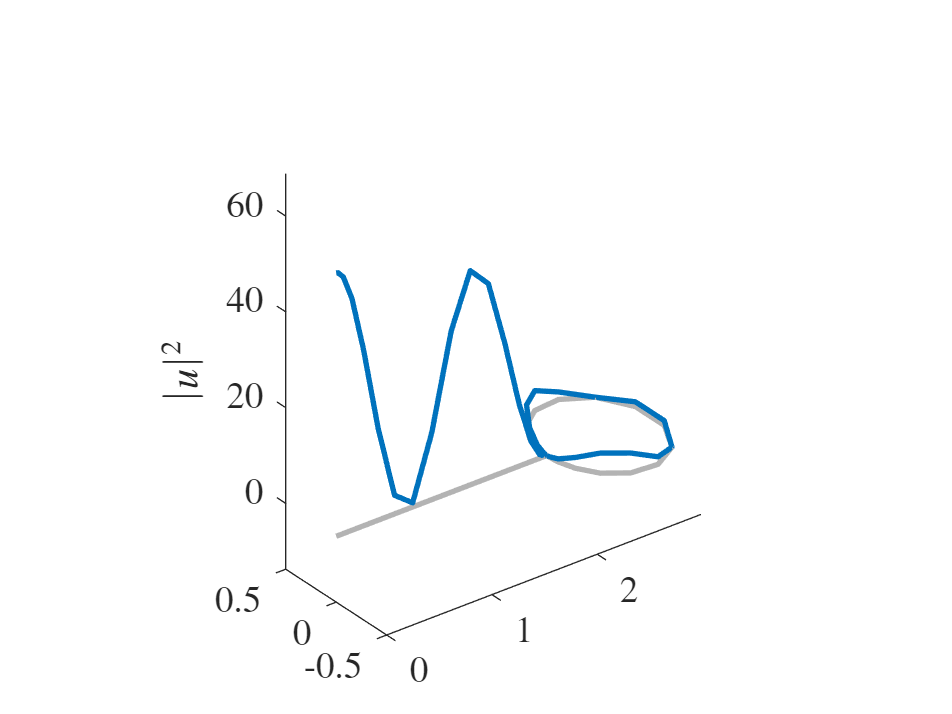

[evec,eval] = Phi.eigs(8);
lambda1 = eval(3);
lambda2 = eval(5);
u0 = lambda1.*evec(:,3)+lambda2.*evec(:,5);
Phi.plot(abs(u0).^2)
zlabel('$|u|^2$')
daspect([1.25 1 30])

Evolving the solution in time

tend = 0.1;
% [t,u] = Phi.timeEvolve15s(f,u0,tend);
[t,u] = Phi.timeEvolveARK(f,u0,10^-01,tend);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the 

## Plotting the solution

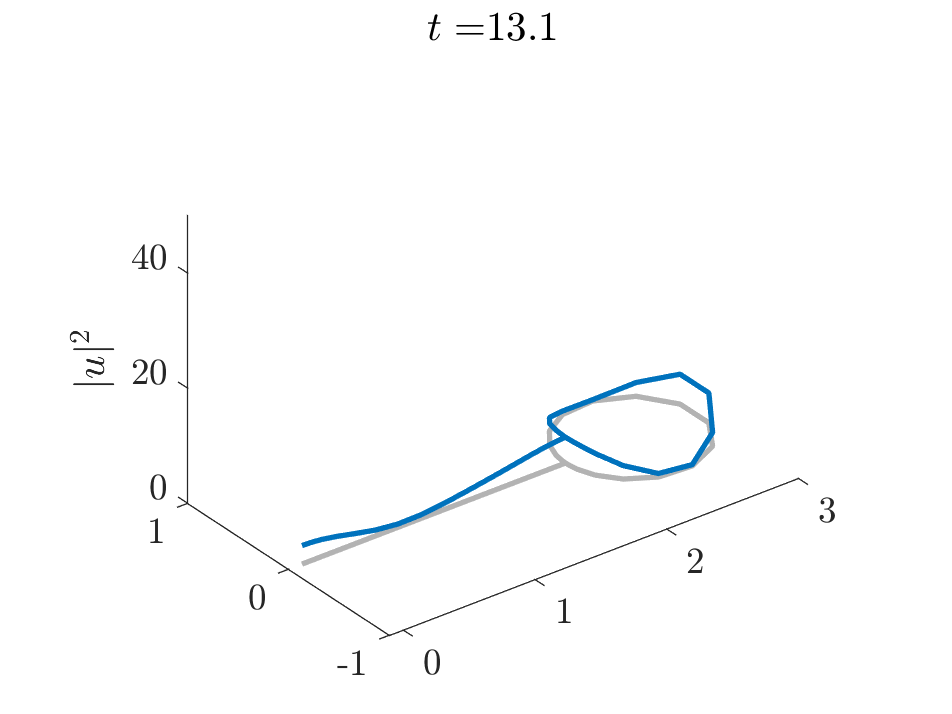

n = size(u,2);
scale=1; %floor(n/100);
for i=1:floor(n/scale)
    clf
    Phi.plot(abs(u(:,scale*i)).^2)
    axis([-0.1 3 -1 1 0 50])
    daspect([1 1 25])
    title(['$t=$',num2str(round(t(scale*i),2))])
    zlabel('$|u|^2$')
    pause(.0000000001)
end

## Error Analysis

Compare our numerical solution to the analytical one. 

uana = @(t) exp(1i*lambda1*t)*lambda1.*evec(:,3)+exp(1i*lambda2*t)*lambda2.*evec(:,5);

error = zeros(1,size(u,2));
for i=1:size(u,2)
    error(i) = max(abs(uana(t(i)) - u(:,i)));
end

disp('The error found by comparing the numerical and analytical solutions is:')

The error found by comparing the numerical and analytical solutions is:


disp(abs(max(error)))

   3.946355600872846



We also check for conservation of energy and mass.

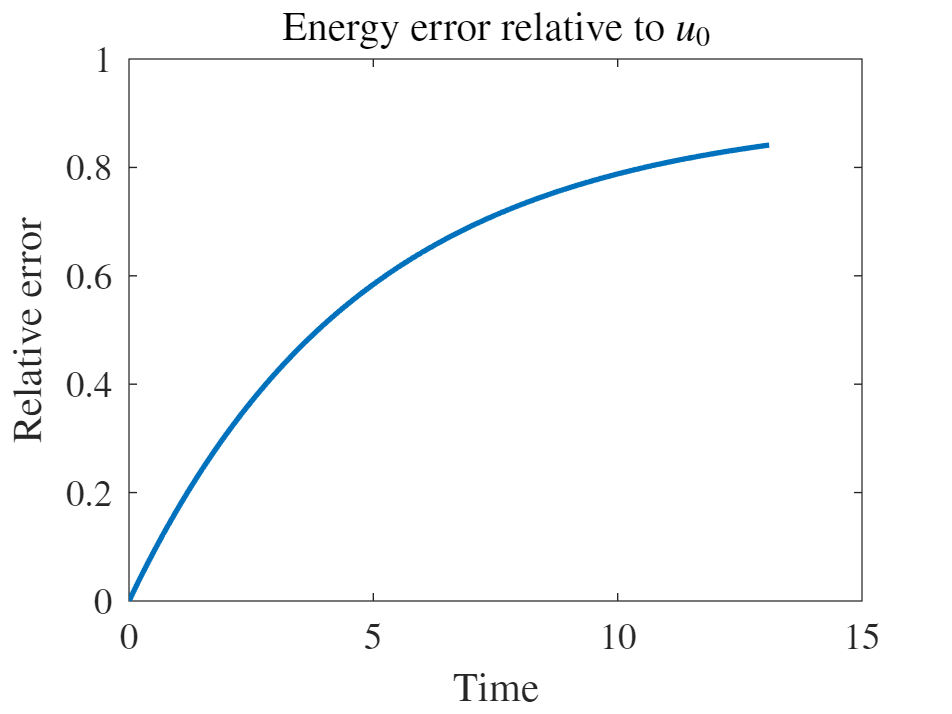

energyDiff = zeros(floor(n/scale),1);
massDiff = zeros(floor(n/scale),1);
tplot = zeros(floor(n/scale),1);
C = Phi.weightMatrixWithBCs;
Cinv = pinv(C);

u0energy = 0.5*Phi.dot( Cinv*A*u0 , conj(u(:,1)) );
u0mass = Phi.dot(u(:,1),conj(u(:,1)));
[~,~,nxTot] = Phi.nx;
nEdges = 2;


for i=1:floor(n/scale)
    ui = u(:,scale*i);
    energyDiff(i) = abs( (0.5*Phi.dot(Cinv*A*ui,conj(ui)) - u0energy) / u0energy );
    massDiff(i) = abs( (Phi.dot(ui,conj(ui)) - u0mass) / u0mass );
    tplot(i) = t(scale*i);
end

disp('')
disp('')
figure
plot(tplot,energyDiff)
title('Energy error relative to $u_0$')
xlabel('Time')
ylabel('Relative error')

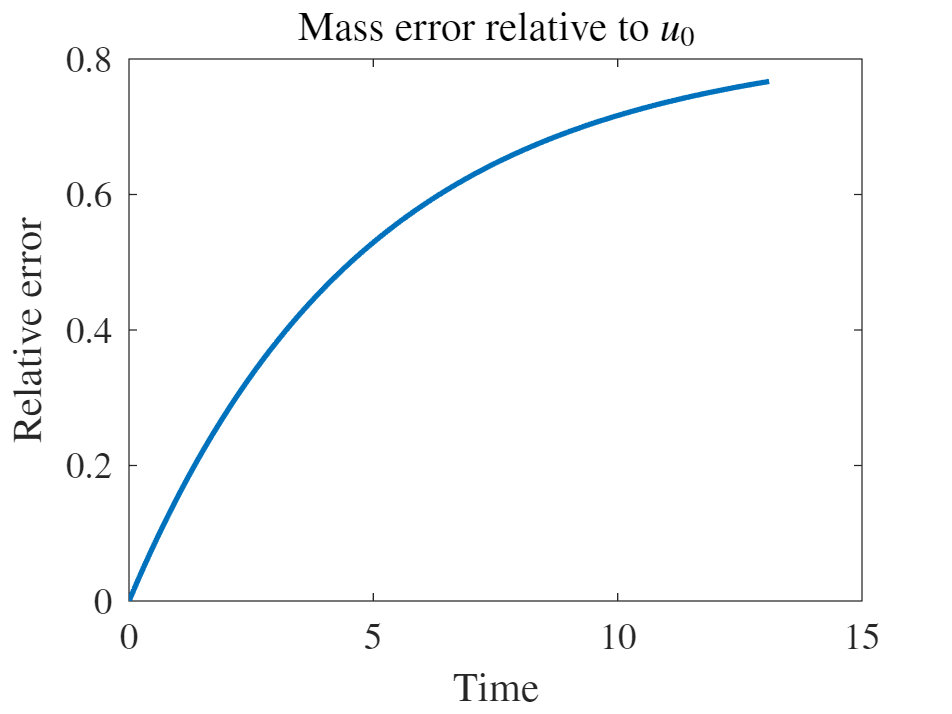


figure
plot(tplot,massDiff)
title('Mass error relative to $u_0$')
xlabel('Time')
ylabel('Relative error')

Analyzes the rate of convergence for this method

% Nt = [10 20 50 100 200 500 1000];
% conv = zeros(length(Nt),2);
% for j=1:length(Nt)
%     h = 0.1/Nt(j);
%     tic
%     [t,u] = Phi.timeEvolveARK(f,u0,h,tend);
%     toc
% 
%     error = zeros(1,size(u,2));
%     for i=1:size(u,2)
%         error(i) = max( abs((uana(t(i)) - u(:,i))./uana(t(i))) );
%     end
%     
%     conv(j,:) = [tend/h,max(error)];
% end


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the 

Elapsed time is 68.309681 seconds.



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the 

Elapsed time is 135.620904 seconds.



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the 

% 
% figure
% loglog(conv(:,1),conv(:,2),'r*')
% xlabel('$N_t$')
% ylabel('Error')
% yticks([10^-12 10^-10 10^-8 10^-6 10^-4 10^-2 10^0])

Spatial analysis

% iterations = 8;
% conv = zeros(iterations,2);
% for j=1:iterations
%     nx = 4*(j+1);
%     Phi = quantumGraphFromTemplate('multibell','discretization','Chebyshev','nX',nx,'nbells',1);
%     A = Phi.laplacianMatrix;
%     f = @(t,z) 1i * A*z;
% 
%     [evec,eval] = Phi.eigs(8);
%     lambda1 = eval(3);
%     lambda2 = eval(5);
%     u0 = lambda1.*evec(:,3)+lambda2.*evec(:,5);
%     tend = 0.1;
%     [t,u] = Phi.timeEvolveARK(f,u0,10^(-03),tend);
% 
%     uana = @(t) exp(1i*lambda1*t)*lambda1.*evec(:,3)+exp(1i*lambda2*t)*lambda2.*evec(:,5);
%     maxdiff = zeros(1,size(u,2));
%     for i=1:size(u,2)
%         maxdiff(i) = max(uana(t(i)) - u(:,i));
%     end
%     conv(j,:) = [nx,max(abs(maxdiff))];
% end
% 
% plot(conv(:,1),conv(:,2),'r*')
% set(gca, 'YScale', 'log')
% xticks(conv(:,1))
% xlabel('$N_x$')
% ylabel('Error')